Christoffer Mølck

Eks nr: 187952

Std nr: 202009347

# Opgave 1. 

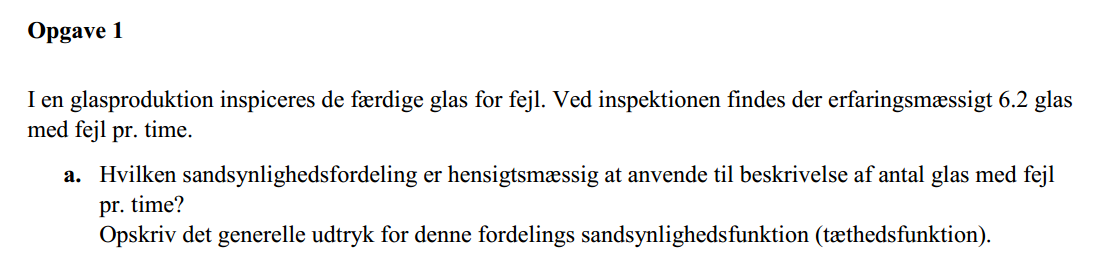

Da vi har et gøre med nået pr tid eller pr enhed ville det være en god ide at pro poissons fordeling. 

## 
$$p\left(y\right)=\frac{\lambda^y }{y!}e^{-\lambda }$$


__________________

u = 6.2 %Middelværdig også ligmed lamda

u = 6.2000

varians = u 

varians = 6.2000

stdafvigelse = sqrt(varians)

stdafvigelse = 2.4900

lambda = 6.2

lambda = 6.2000

poisspdf(4, lambda) %den ikke komuleret chance

ans = 0.1249

1 - poisscdf(4, lambda) %chancen må være 1 - den samlet sandsynlighed for 1 - 4. 

ans = 0.7408

% det ville sige alt over 5 uden grænse ville være 
% inkluderet i den chance. Den burde være høj da der generelt 
% produceres 6.2 fejl i timen. 
%det passer meget godt.

%Nu skal vi egentlig gøre det samme men fratrække det øverste så vi ikke
%får en uendelig høj, altså vi ligge en grænse fra 5:9.
(1 - poisscdf(4, lambda)) - (1 - poisscdf(10, lambda))

ans = 0.6894

%jeg tænker poisscdf(10) da 9 skal inkluderes. og tænker at poisscdf tager
%til 9.9999~ men ikke 10

jeg tænker at vis det er over 2 timer så må mængden af fejl være fordoblet, så lamda = 12.4 fejl. 

lambda_2t = 6.2 * 2

lambda_2t = 12.4000

poisspdf(10, lambda_2t) %NETTOP 10 fejl, så chancen for at få lige precis den mængde fejl er ikke så stor. 

ans = 0.0975

# Opgave 2. 

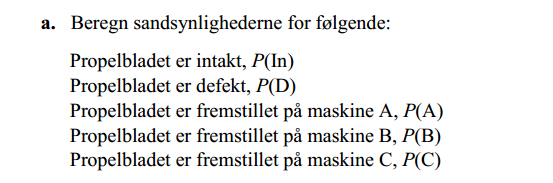

Totalt = 50 + 45 + 45 %Total mængde produceret på alle maskiner

Totalt = 140

In_tot = 39 + 41 + 36 %Mængde produceret som er OK på alle maskiner

In_tot = 116

D_tot = 11 + 4 + 9 %Mængde produceret som er er defejte på alle maskiner

D_tot = 24

P_in = In_tot/Totalt %Chance for at delen er OK 

P_in = 0.8286

P_D = D_tot/Totalt %Chance for delen er defekt

P_D = 0.1714

%Eller
P_D = 1 - P_in %Chance for delen er defekt

P_D = 0.1714

P_A = 50 / Totalt %Mængden produceret på maskine A

P_A = 0.3571

P_B = 45 / Totalt %Mængden produceret på maskine B

P_B = 0.3214

P_C = 45 / Totalt %Mængden produceret på maskine C

P_C = 0.3214

P_A + P_B + P_C %Skal give 1, sanity check

ans = 1

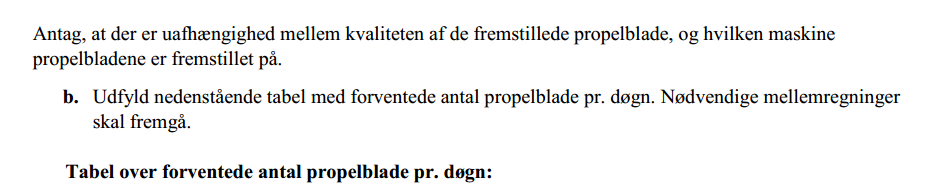

Der laves en KontingensTabel

% rowsum = sum(InputData,2); Udregninger brugt
% colsum = sum(InputData,1);
% 
% total = sum(colsum);
% 
% rows = size(rowsum,1);
% cols = size(colsum,2);
% 
% rowfreq = rowsum/total;
% colfreq = colsum/total;
% 
% E = zeros(rows, cols);
% 
% for i = 1:rows
%     for j = 1:cols
%         E(i,j) = total*rowfreq(i)*colfreq(j);
%     end
% end
Tabl = [[39, 11];[41, 4];[36, 9]]

Tabl =     39    11
    41     4
    36     9


KontingensTabel(Tabl);

strings = 1×3 string array
    "A"    "B"    "C"


     Data navn          In | D     
    ___________    ________________

    "Maskine A"    41.429    8.5714
    "Maskine B"    37.286    7.7143
    "Maskine C"    37.286    7.7143



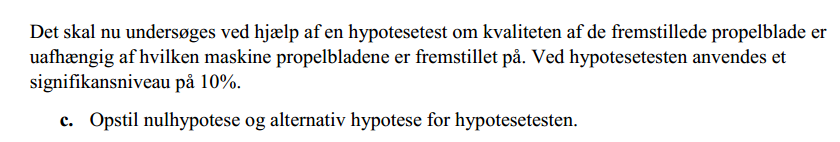

Der skal undersøges om 2 variabler er uafhængige så en chi i anden test bruges.

Til denne opsættes hypostesen:

H0 = Kvaliteten af det produceret propelblad er afhængig af maskinen

Ha = Kavliteten af det produceret propelblad er IKKE afhængig af maskinen

Tabl = [[39, 11];[41, 4];[36, 9]]

Tabl =     39    11
    41     4
    36     9


displayFormula("chi_0^2 = (Sigma_i)^k*(Sigma_j)^k*((O_ij - E_ij)^2/E_ij)") 

$${\chi_{0}}^{2}={\Sigma_{i}}^{k}\,{\Sigma_{j}}^{k}\,\frac{{\left(O_{\mathrm{ij}}-E_{\mathrm{ij}}\right)}^{2}}{E_{\mathrm{ij}}}$$

Da det det er antal fejl over en vis mængde tid, er det formentlig en poission fordeling. 

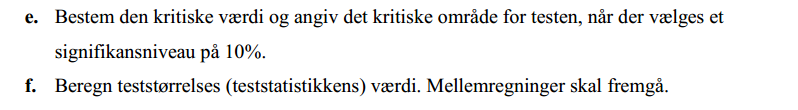


forv = KontingensTabel(Tabl) %Først lave en kontigens tabel til testen. 

     Data navn          In | D     
    ___________    ________________

    "Maskine A"    41.429    8.5714
    "Maskine B"    37.286    7.7143
    "Maskine C"    37.286    7.7143



forv =    41.4286    8.5714
   37.2857    7.7143
   37.2857    7.7143


Tabl = [[39, 11] ;[41, 4];[36, 9]]' %Rotere så de kan bruges i funk

Tabl =     39    41    36
    11     4     9


forv = [forv(1,:); forv(2,:); forv(3,:)]' %Rotere så de kan bruges i funk

forv =    41.4286   37.2857   37.2857
    8.5714    7.7143    7.7143


Formel for teststørrelsen


$${\chi_{0}}^{2}={\Sigma_{i}}^{k}\,{\Sigma_{j}}^{k}\,\frac{{\left(O_{\mathrm{ij}}-E_{\mathrm{ij}}\right)}^{2}}{E_{\mathrm{ij}}}$$

-----------------------------------------------------------------
Antal frihedsgrader


$$\mathrm{dfs}=\left(r-1\right)\,\left(c-1\right)$$

-----------------------------------------------------------------
Kritiske grænse - MATLAB kommando


$${\chi_{\alpha }}^{2}=\mathrm{chi2inv}\,\alpha \,\mathrm{dfs}$$

-----------------------------------------------------------------
    Signifikansniveau    Frihedsgrader    Kritisk grænse    Teststørrelse
    _________________    _____________    ______________    _____________

          "%90"                2             0.21072           2.9888    



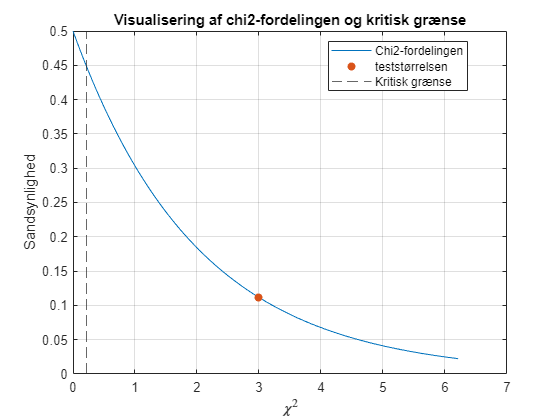

chi2normal_Test_8_uafh(Tabl, forv, 10) %Funktion til chi2 test 

Det kan hurtigt se at testørelsen > kritiske grænse. Derfor må vi forkaste H0 og sige at Ha er sand, det ville sige at kavliteten af det produceret propelblad er IKKE afhængig af maskinen og derfor godt kan producere på alle maskiner lige meget uden at være bekymret for at nogle af dem laver flere fejl en andre.

p = 1 - chi2cdf(2.988, 2)

p = 0.2245

# Opgave 3. 

data = importdata("Christoffer\StatEksamen\Data_M4STI1_2023F.xlsx", "H:I")

data = struct with fields:
        data: [14×7 double]
    textdata: {4×9 cell}


data = data.data(:,6:7);

data =          0   22.7000
    5.0000  165.5000
   10.0000  236.5000
   10.0000  214.3000
   15.0000  255.6000
   20.0000  226.1000
   20.0000  255.0000
   25.0000  249.7000
   25.0000  233.6000
   30.0000  254.8000


data_x = data(:,1);
data_y = data(:,2); %Nået data import sjov. 


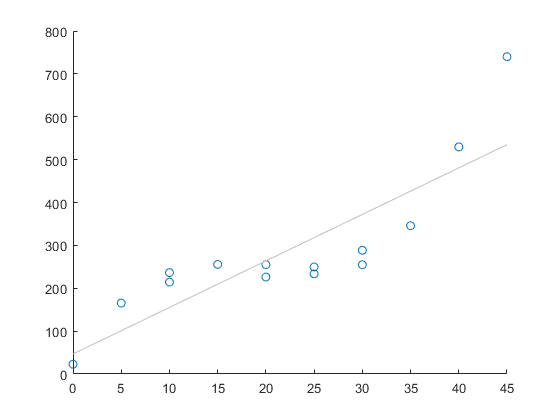

%Jeg laver lige et scatter plot først får at få overblik over data
figure(1)
scatter(data_x, data_y)
lsline

%Ja det gør det jo ret tydligt at linær nok ikke ligefrem er den beste
%model til denne data. 

mdl = fitlm(data_x, data_y)

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    ______    _______    __________

    (Intercept)      46.73     49.296    0.94795       0.36186
    x1              10.851     1.9283     5.6275    0.00011118


Number of observations: 14, Error degrees of freedom: 12
Root Mean Squared Error: 92.2
R-squared: 0.725,  Adjusted R-Squared: 0.702
F-statistic vs. constant model: 31.7, p-value = 0.000111

syms x
y(x) = 46.73 + 10.851 * x %ville være ligningen

$$y(x) = \frac{10851\,x}{1000}+\frac{4673}{100}$$

Ud fra r^2 adjusted kan vi se at den ligger på en 0.7 hvilket ikke er fantastisk og betyder at vores model nok ikke passer særlig godt til dataen. 

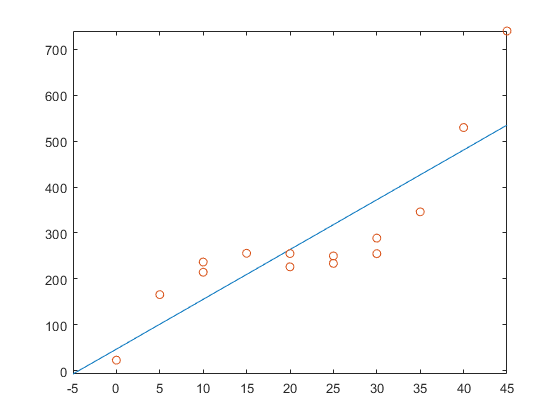



fplot(y(x))
hold on
scatter(data_x, data_y)
hold off

plottet er heldigvis identisk med sanity plottet jeg lavet først i ogave a. Det burde den da også helst være men godt nok lige at tjække at alt stemmer overens. 

Sammenhængende imellem regressor og responsvariabel ses som at være positiv da vi ser en positiv trænd i både fit linjen men også i scatter dataen. 

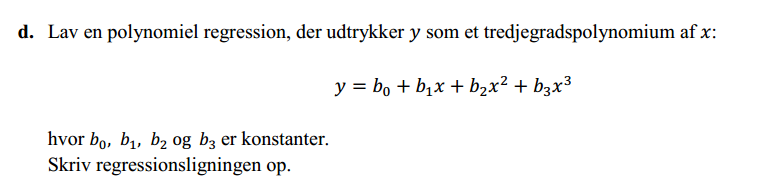

polyfit = fitlm(data_x, data_y, 'y ~ x1 + x1^2 + x1^3')

polyfit = Linear regression model:
    y ~ 1 + x1 + x1^2 + x1^3

Estimated Coefficients:
                   Estimate       SE         tStat       pValue  
                   ________    _________    _______    __________

    (Intercept)      27.325       14.127     1.9343      0.081848
    x1               35.085       2.6749     13.116    1.2604e-07
    x1^2            -1.8455      0.13924    -13.254     1.141e-07
    x1^3           0.031651    0.0020149     15.708    2.2424e-08


Number of observations: 14, Error degrees of freedom: 10
Root Mean Squared Error: 15.7
R-squared: 0.993,  Adjusted R-Squared: 0.991
F-statistic vs. constant model: 498, p-value = 3.5e-11

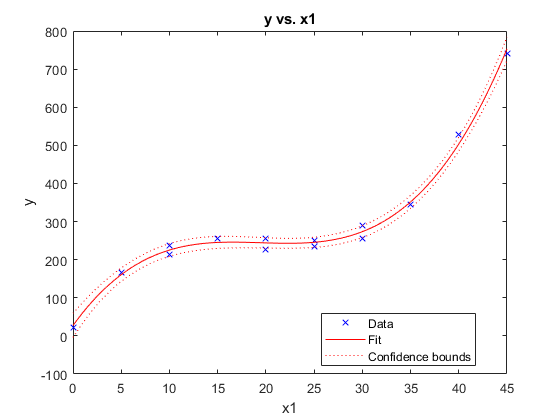

plot(polyfit)

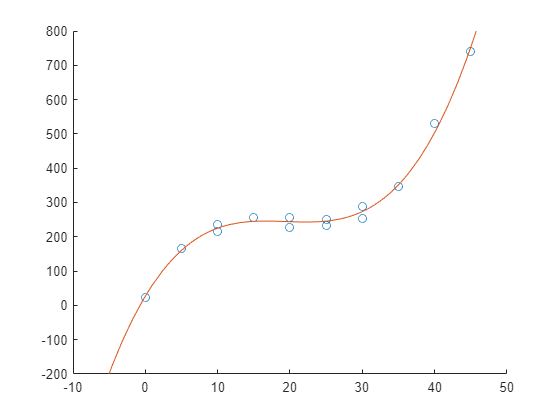

scatter(data_x, data_y)
y(x) = 27.325 + 35.085 * x + -1.8455 * x^2 + 0.031651 * x^3;
hold on
fplot(y(x))
hold off %Sanity check, det passer ganske fint


y(x) = 27.325 + 35.085 * x + -1.8455 * x^2 + 0.031651 * x^3 % ville være vores polynomie

$$y(x) = \frac{2280694908894457\,x^{3}}{72057594037927936}-\frac{3691\,x^{2}}{2000}+\frac{7017\,x}{200}+\frac{1093}{40}$$

Ja markant bedre. R^2 korrigeret er helt oppe på 0.991 hvilket er en rigtig godt passende model.

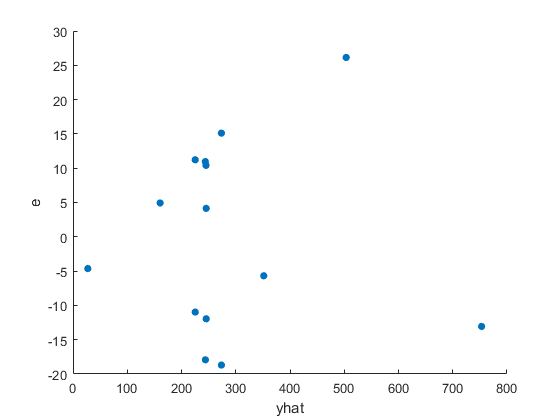

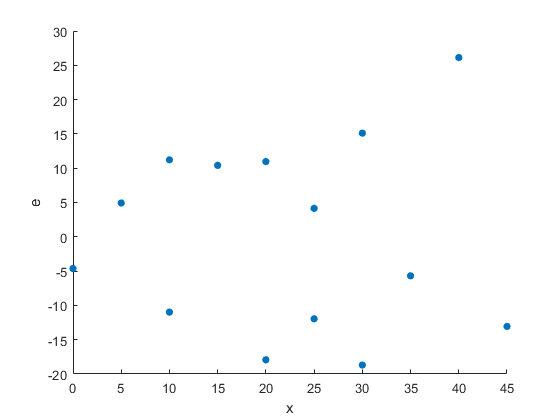

ris = struct with fields:
         data: [14×9 table]
            k: 1
            n: 14
    lev_limit: 0.2857
    rst_limit: 3


ris = STAT.Residual(polyfit, [data_x, data_y])

Jammen det ser sådan set ganske findt ud. Risidualerne ligger tilfældigt hvilket er som ønsket og viser at poly modellen passer godt med dataen. Der er ingen trends. 

ris.data

ans = 14×9 table
    x       y        lev        rst       levrage    outlier     yhat            yci             resid 
    __    _____    _______    ________    _______    _______    ______    __________________    _______

     0     22.7    0.80909    -0.65452       1          0       27.325    -4.1508     58.802    -4.6255
     5    165.5    0.25114     0.34643       0          0       160.57     143.03     178.11     4.9301
    10    236.5    0.22474     0.79663       0          0       225.28     208.69     241.87     11.223
    10    214.3    0.22474      -0.778       0          0       225.28     208.69     241.87    -10.977
    15    255.6    0.20192     0.72448       0      

ris.data.levrage(1)

ans = 1

ris.data.levrage(14)

ans = 1

Det ses at vi har 2 løftestangs punkter (levrage) ved x = 0 og x = 45. Ud fra risidual plottet virker de ikke til at være gale nok til at være til bekymring og kan ignoreres uden problemer. Nok grundet af de ligger ved polynomiets kraftigste hældning som får y værdigen til at ændre sig kraftigt på meget få x. 

vpa(y(27), 5)

$$ans = 252.24$$

coefCI(polyfit, 0.05)

ans =    -4.1508   58.8018
   29.1250   41.0453
   -2.1557   -1.5353
    0.0272    0.0361


y_h(x) = 58.8018 + 41.0453 * x + -1.5353 * x^2 + 0.0361 * x^3 

$$y\_h(x) = \frac{361\,x^{3}}{10000}-\frac{15353\,x^{2}}{10000}+\frac{180519138462217\,x}{4398046511104}+\frac{4137808821386163}{70368744177664}$$

y_l(x) = -4.1508 + 29.1250 * x + -2.1557 * x^2 + 0.0272 * x^3 

$$y\_l(x) = \frac{17\,x^{3}}{625}-\frac{21557\,x^{2}}{10000}+\frac{233\,x}{8}-\frac{10377}{2500}$$

vpa(y_h(27), 5) - vpa(y(27), 5)

$$ans = 506.11036700004478916525840759277$$

vpa(y(27), 5) - vpa(y_l(27), 5)

$$ans = 506.14063299997360445559024810791$$

%Det ville sige at 252.42 +- 506.1 cirka. hvilket ikke lyder helt
%rigtigt... 


# Opgave 4.